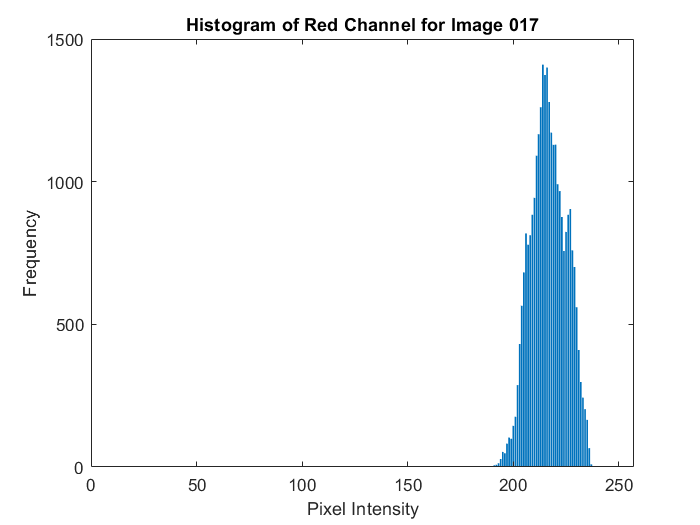

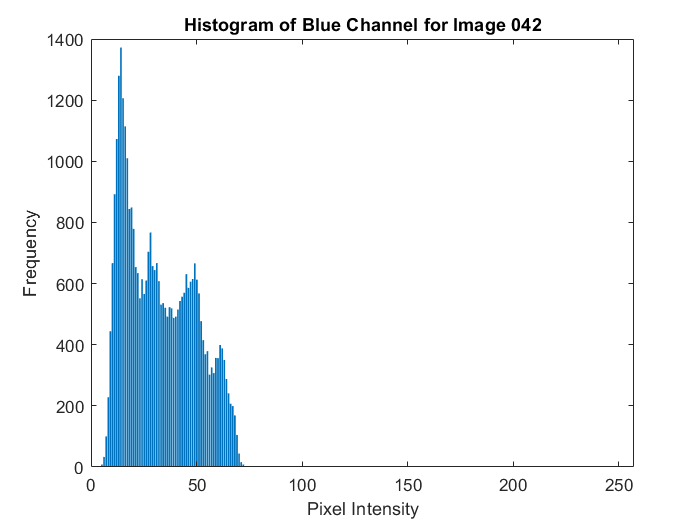

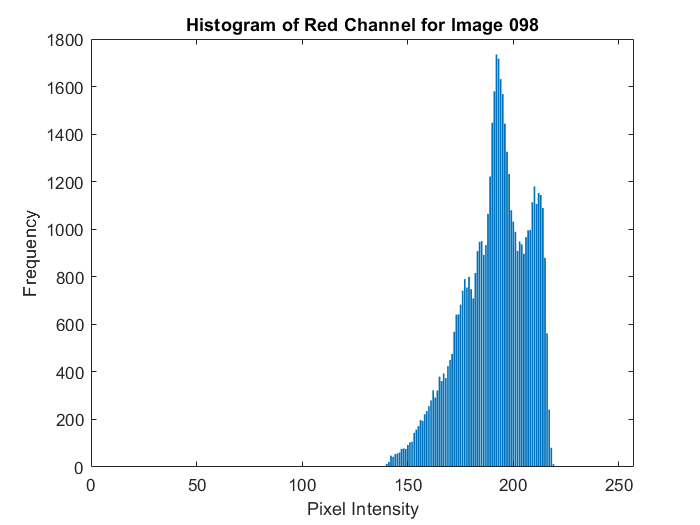

% List of specific image numbers
imageNumbers = [17, 32, 36, 37, 40, 42, 49, 57, 60, 63, 64, 66, 68, 69, 80, 81, 84, 88, 94, 98];

% Base directories for the images and ground truth
baseDirImages = 'F:/Semester 6/Pengolahan Citra Biomedika/Tubes/Images/training/';
baseDirGT = 'F:/Semester 6/Pengolahan Citra Biomedika/Tubes/GT/Training/';

% Output directory for the overlay images
outputDir = 'F:/Semester 6/Pengolahan Citra Biomedika/Tubes/OverlayOutput/';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Output directory for the histograms
histOutputDir = fullfile(outputDir, 'Histograms OC Training');
if ~exist(histOutputDir, 'dir')
    mkdir(histOutputDir);
end

for i = 1:length(imageNumbers)
    % Get the current image number
    imageNumber = imageNumbers(i);
    
    % Generate filenames for the images
    imageFile = fullfile(baseDirImages, sprintf('drishtiGS_%03d.png', imageNumber));
    gtFile = fullfile(baseDirGT, sprintf('drishtiGS_%03d', imageNumber), sprintf('drishtiGS_%03d_CupAvgBoundary_OC_img.png', imageNumber));
    
    % Check if the files exist
    if isfile(imageFile) && isfile(gtFile)
        % Read the images
        img = imread(imageFile);
        gtImg = imread(gtFile);
        
        % Convert the ground truth image to a logical mask
        gtMask = logical(gtImg);
        
        % Convert the main image to RGB if it's grayscale
        if size(img, 3) == 1
            img = repmat(img, [1, 1, 3]);
        end
        
        % Create a masked version of the original image
        overlayImg = img;
        for channel = 1:3
            channelData = img(:,:,channel);
            channelData(~gtMask) = 0;
            overlayImg(:,:,channel) = channelData;
        end
        
        % Save the overlay image to the output directory
        outputFileName = fullfile(outputDir, sprintf('overlay_%03d.png', imageNumber));
        imwrite(overlayImg, outputFileName);
        
        % Generate and save histograms for the red, green, and blue channels
        channelNames = {'Red', 'Green', 'Blue'};
        for channel = 1:3
            channelData = overlayImg(:,:,channel);
            histValues = imhist(channelData(gtMask));
            
            % Create a figure for the histogram
            figure;
            bar(histValues);
            title(sprintf('Histogram of %s Channel for Image %03d', channelNames{channel}, imageNumber));
            xlabel('Pixel Intensity');
            ylabel('Frequency');
            
            % Save the histogram figure
            histFileName = fullfile(histOutputDir, sprintf('hist_%s_%03d.png', channelNames{channel}, imageNumber));
            saveas(gcf, histFileName);
            close;
        end
    else
        fprintf('Files not found for image number: %03d\n', imageNumber);
    end
end